clear;

% Eb/N0 Values
EbN0_dB = 0:5:20;
EbN0_linear = 10.^(EbN0_dB/10);

% Avg Probability Bit Error Vectors
Pe_no_div = zeros(size(EbN0_linear));
Pe_EGC = zeros(size(EbN0_linear));

% Loop Through Eb/N0 Values For EGC & No Diversity
for k = 1:length(EbN0_linear)
    EbN0 = EbN0_linear(k);
    
    % No Diversity
    Pe_no_div(k) = 0.8*qfunc(sqrt(2*EbN0)) + 0.2*qfunc(sqrt(0.02*EbN0));
    
    % 2-Branch EGC
    Pe_EGC(k) = 0.64*qfunc(sqrt(4*EbN0)) + 0.32*qfunc(sqrt(1.22*EbN0)) + 0.04*qfunc(sqrt(0.04*EbN0));
end

% Percent Reduction
percent_reduction = ((Pe_no_div - Pe_EGC) ./ Pe_no_div) * 100;

% Print Out Results
fprintf('Eb/N0(dB)   Pe NoDiv    Pe EGC      Percent Reduction\n');

Eb/N0(dB)   Pe NoDiv    Pe EGC      Percent Reduction


for k = 1:length(EbN0_dB)
    fprintf('%2d          %.6f    %.6f    %.2f%%\n', EbN0_dB(k), Pe_no_div(k), Pe_EGC(k), percent_reduction(k));
end

 0          0.151673    0.074487    50.89%
 5          0.084907    0.022484    73.52%
10          0.065475    0.010618    83.78%
15          0.042646    0.005214    87.77%
20          0.015730    0.000910    94.21%


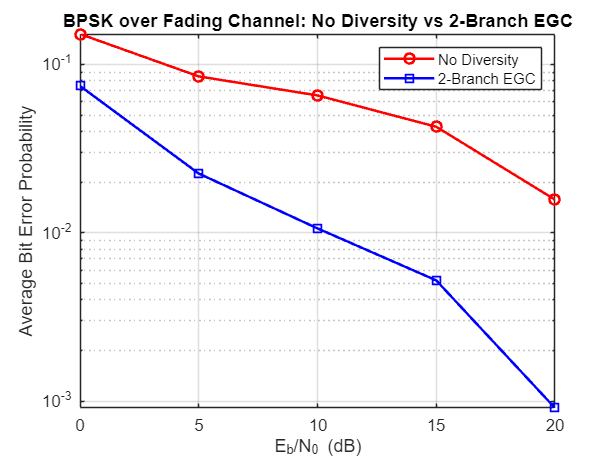


% Plot Semilogy Graph
figure;
semilogy(EbN0_dB, Pe_no_div, 'ro-','LineWidth', 1.5); 
hold on;
semilogy(EbN0_dB, Pe_EGC, 'bs-','LineWidth', 1.5);
grid on;
xlabel('E_b/N_0 (dB)');
ylabel('Average Bit Error Probability');
title('BPSK over Fading Channel: No Diversity vs 2-Branch EGC');
legend('No Diversity','2-Branch EGC');